## Problem 2

Consider two independent Poisson random variables $X$ and $Y$ , with parameters $\lambda_X := 3$ and $\lambda_Y := 4$. 

lmd_x=3;
lmd_y=4;

k_vals=(0:25);

- Define a random variable $Z := X + Y$ , having a probability mass function (PMF) $P(Z)$. 

 (i) Empirically obtain an estimate $\hat{P}(Z)$ of the PMF $P(Z)$, by drawing $N = 10^6$ instances (sample points) of $X$ and $Y$ both. You may use the poissrnd(.) function in Matlab. Report the values of $\hat{P}(Z = k)$ for $k = 0, 1, 2, \cdots , 25$. 

N=10^6; 
% Z = X + Y we do for all instances together
Z_1 = poissrnd(lmd_x,N,1)+poissrnd(lmd_y,N,1)

Z_1 =      7
     4
     7
     4
    10
     9
    11
     8
     1
     4


P_emp_1 = hist(Z_1,k_vals);
P_emp_1 = P_emp_1 / sum(P_emp_1)

P_emp_1 =     0.0009    0.0063    0.0226    0.0520    0.0914    0.1286    0.1491    0.1486    0.1304    0.1016    0.0705    0.0448    0.0264    0.0144    0.0070    0.0032    0.0015    0.0006    0.0002    0.0001    0.0000    0.0000         0         0         0         0


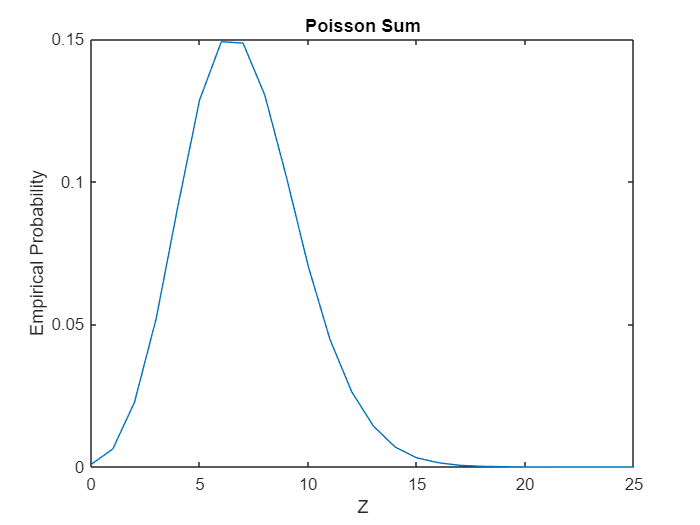

plot(k_vals,P_emp_1), xlabel("Z"), ylabel("Empirical Probability"), title("Poisson Sum");

(ii) What will the PMF $P(Z)$ be theoretically/analytically ? 

The poisson distribution is


$$P_\lambda(a) = \frac{\lambda^a}{a!} e^{-\lambda}$$


$P(Z=z)$ is


$$P(Z=z) = \sum_{x=0}^z P(X=x)\cdot P(Y=z-x)$$



$$= \sum_{x=0}^z \frac{\lambda_x^x}{x!}\frac{\lambda_y^{z-x}}{(z-x)!} e^{-\lambda_x -\lambda_y}$$



$$= \sum_{x=0}^z \frac{(\lambda_x/\lambda_y)^x \cdot{ }^zC_x}{z! } \lambda_y^z e^{-\lambda_x -\lambda_y}$$



$$= \frac{(\lambda_x+\lambda_y)^z}{z!} e^{-(\lambda_x+\lambda_y)}$$


This is a new poisson distribution.

(iii) Show and compare the values for $\hat{P}(Z = k)$ and $P(Z = k)$ for $k = 0, 1, 2, \cdots , 25$.

P_th_1 = (lmd_x+lmd_y).^k_vals * exp(-lmd_x-lmd_y) ./factorial(k_vals);
disp(P_th_1);

  Columns 1 through 10

    0.0009    0.0064    0.0223    0.0521    0.0912    0.1277    0.1490    0.1490    0.1304    0.1014

  Columns 11 through 20

    0.0710    0.0452    0.0263    0.0142    0.0071    0.0033    0.0014    0.0006    0.0002    0.0001

  Columns 21 through 26

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



disp(P_emp_1);

  Columns 1 through 10

    0.0009    0.0063    0.0226    0.0520    0.0914    0.1286    0.1491    0.1486    0.1304    0.1016

  Columns 11 through 20

    0.0705    0.0448    0.0264    0.0144    0.0070    0.0032    0.0015    0.0006    0.0002    0.0001

  Columns 21 through 26

    0.0000    0.0000         0         0         0         0



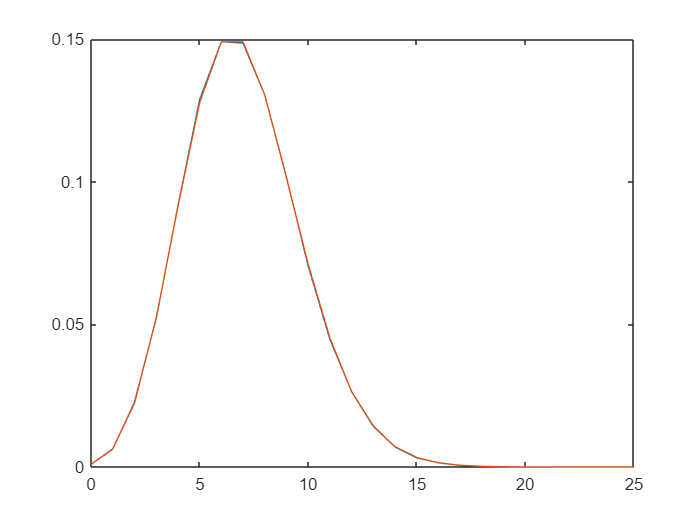

plot(k_vals,P_emp_1); %add labels n shit
hold on;
plot(k_vals,P_th_1);
hold off;

- Implement a Poisson thinning process (as discussed in class) on the random variable Y , where the thinning process uses probability parameter 0.8. Let the thinned random variable be Z.  

(i) Empirically obtain an estimate $\hat{P}(Z)$ of the PMF $P(Z)$, by drawing $N := 10^5$ instances (sample points) from $Y$ . You may use the poissrnd(.) and binornd(.) functions in Matlab. Report the values of $\hat{P}(Z = k)$ for $k = 0, 1, 2, \cdots , 25$. 

N=10^5;
p=0.8;
Y_2= poissrnd(lmd_y,N,1)

Y_2 =      5
     6
     7
     2
     4
     1
     3
     9
     5
     6


Z_2=binornd(Y_2,p)

Z_2 =      4
     4
     6
     1
     4
     1
     2
     7
     4
     5


P_emp_2 = hist(Z_2,k_vals);
P_emp_2 = P_emp_2 /sum(P_emp_2)

P_emp_2 =     0.0401    0.1318    0.2068    0.2237    0.1792    0.1146    0.0604    0.0278    0.0103    0.0036    0.0011    0.0004    0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0


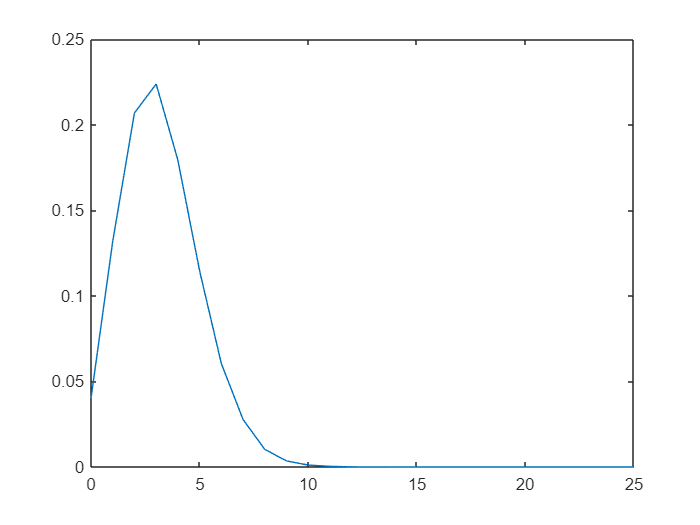

plot(k_vals,P_emp_2), xlabel("Z"), ylabel("Empirical Probability"), title("Poisson Thinning");

(ii) What will the PMF $P(Z)$ be theoretically/analytically ? 

refer slides and fill here


$$= \frac{e^{-\lambda p}(\lambda p)^k}{k!}$$


(iii) Show and compare the values for $\hat{P}(Z = k)$ and $P(Z = k)$ for $k = 0, 1, 2, \cdots , 25$.

P_th_2 = (lmd_y*p).^k_vals * exp(-lmd_y*p) ./factorial(k_vals);

disp(P_th_2);

  Columns 1 through 10

    0.0408    0.1304    0.2087    0.2226    0.1781    0.1140    0.0608    0.0278    0.0111    0.0040

  Columns 11 through 20

    0.0013    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

  Columns 21 through 26

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



disp(P_emp_2);

  Columns 1 through 10

    0.0401    0.1318    0.2068    0.2237    0.1792    0.1146    0.0604    0.0278    0.0103    0.0036

  Columns 11 through 20

    0.0011    0.0004    0.0001    0.0000         0         0         0         0         0         0

  Columns 21 through 26

         0         0         0         0         0         0



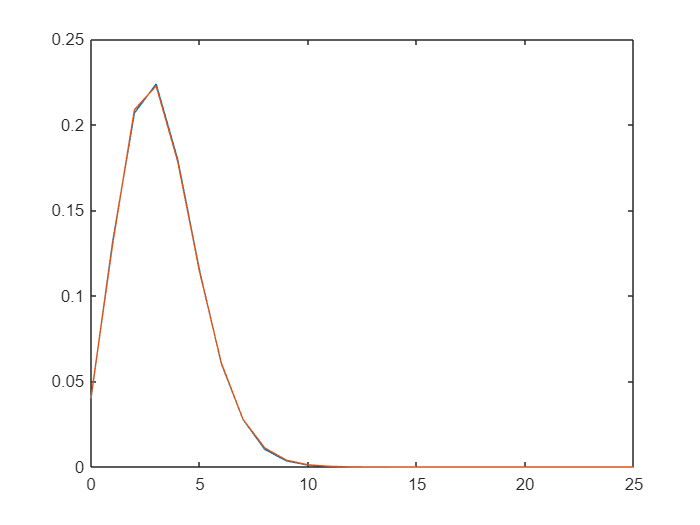

plot(k_vals,P_emp_2); %add labels n shit
hold on;
plot(k_vals,P_th_2);
hold off;